Part 1

t=0:0.01:200; %inititializing t
G=zeros(1,length(t)); %giving g the proper length
G(1)=293.8; %giving g a starting value
X=zeros(1,length(t)); %giving x the proper length
X(1)=0; %initializing first value of x
I=zeros(1,length(t)); %giving I proper length
I(1)=241; %giving i a starting value


%Normal Function Parameters
Gb= 92;
Ib= 7.3;
n=0.3;
g=0.003349;
h=89.5;
p1=0.03082;
p2=0.02093;
p3=0.1062 * 10^-4;


%formulas for eeach value
for i=1:length(t)-1
    G(i+1) = G(i) + 0.01 * (-(p1+X(i))*G(i)+p1*Gb);
    %tests if it goes below 0
    if G(i+1)<0
        G(i+1)=0;
    end
    X(i+1) = X(i) + 0.01 * ((-p2*X(i)+p3*(I(i)-Ib)));
    %tests if it goes below 0
    if X(i+1)<0
        X(i+1)=0;
    end
    I(i+1) = I(i) + 0.01 * ((-n*(I(i)-Ib)+g*(G(i)-h)*t(i)));
    %tests if it goes below 0
    if I(i+1)<0
        I(i+1)=0;
    end
end

subplot(2,1,1)

plot(t,G)
title('Glucose')
xlabel('time (min)')
ylabel('G(t) (mg/dL)')
subplot(2,1,2)

plot(t,I)
title('Insulin')
xlabel('time (min)')
ylabel('I(t) (uU/mL)')

Part 2

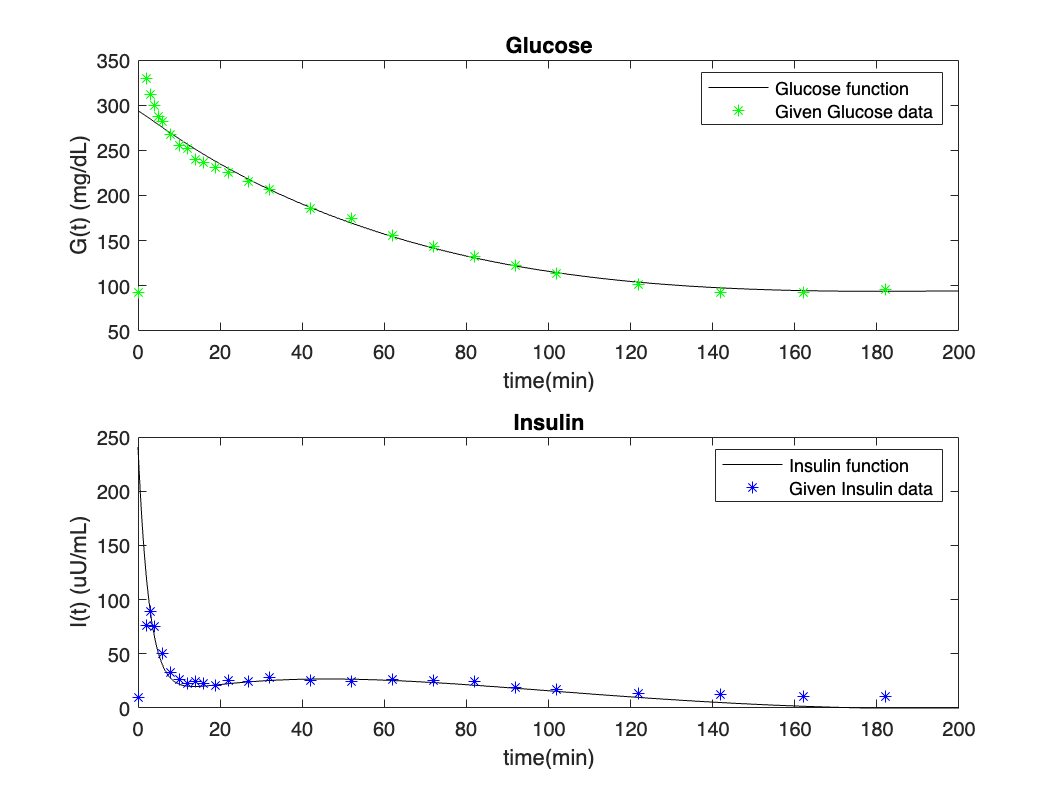

%reading from files
glucosefile = dlmread('Glucose.txt',',');
insulinfile = dlmread('Insulin.txt', ',');

%isolating x and y values for comparison to function
glucosex = glucosefile(:,1);
glucosey = glucosefile(:,2);
insulinx = insulinfile(:,1);
insuliny = insulinfile(:,2);

%declaring variables for glucose-insulin functions later
G1 = 293.8; 
Gb= 95.4;
Ib= 9.9;
n= 0.3606;
g= 0.001785;
p2=0.01301;
p3=0.4031 * 10^-5;

%declaring size of k vector and error arrays
kvector = 0.01:0.0001:0.02;
% errorGarray = zeros(size(kvector));
% errorIarray = zeros(size(kvector));
for k = kvector

    %Eulers method
    [~,t,G,I] = Eulersmethod(k);

    %gets index of values that match with glucose and insulin.txt
    Newg = ismember(t,glucosex);
    G_trend = G(Newg);

    Newi = ismember(t,insulinx);
    I_trend = I(Newi);




    %error of each line
    errorg = sum((glucosey'-G_trend).^2);
    errori = sum((insuliny'-I_trend).^2);


    if k == 0.01
        SmallestErrorG = errorg;
        SmallestErrorI = errori;
    end

    if (errorg+errori)<(SmallestErrorG+SmallestErrorI)
        SmallestErrorG = errorg;
        SmallestErrorI = errori;
    p1 = k;
    end

end

%doing Eulers method again to change g and i back to poper values
[Imax,t,G,I] = Eulersmethod(p1);

%formulas for each insulin guage
s1 = p3/p2;
sg = p1;
phi1= (Imax-Ib)/(n*(G1-Gb));
phi2 = g*10^4;

%plotting the figures with black lines and coloreed stars
figure(1)
subplot(2,1,1)
plot(t,G, 'k')
hold on
plot(glucosex,glucosey, 'g*')
title('Glucose')
xlabel('time(min)')
ylabel('G(t) (mg/dL)')
legend('Glucose function', 'Given Glucose data')
subplot(2,1,2)
plot(t,I, 'k')
hold on
plot(insulinx,insuliny, 'b*')
title('Insulin')
xlabel('time(min)')
ylabel('I(t) (uU/mL)')
legend('Insulin function', 'Given Insulin data')




%tests if values are within range for s1, and displays colored messages
if s1 < 4.0*10^-4 || s1 > 8.0*10^-4
    cprintf('red', 'WARNING your S1 levels are %f (not within safe range). please inform your physician\n', s1)
elseif s1 >= 4.0*10^-4 || s1 <= 8.0*10^-4
    cprintf('green', 'your s1 levels are %f (within safe range)\n', s1)
end

WARNING your S1 levels are 0.000310 (not within safe range). please inform your physician


%tests if values are within range for sg, and displays colored messages
if sg <= 2.1*10^-2
    cprintf('red', 'WARNING your Sg levels are %f (not within safe range). please inform your physician\n', sg)
elseif sg > 2.1*10^-2
    cprintf('green', 'your Sg levels are %f (within safe range)\n', sg)
end

WARNING your Sg levels are 0.014200 (not within safe range). please inform your physician


%tests if values are within range for phi1, and displays colored messages
if phi1 < 2.0 || phi1 > 4.0
    cprintf('red', 'WARNING your Phi-1 levels are %f (not within safe range). please inform your physician\n', phi1)
elseif phi1 >= 2.0 || phi1 <= 4.0
    cprintf('green', 'your Phi-1 levels are %f (within safe range)\n', phi1)
end

your Phi-1 levels are 3.230223 (within safe range)


%tests if values are within range for phi2, and displays colored messages
if phi2 < 20 || phi2 > 35
    cprintf('red', 'WARNING your Phi-2 levels are %f (not within safe range). please inform your physician\n', phi2)
elseif phi2 >= 20 || phi2 <= 35
    cprintf('green', 'your Phi-2 levels are %f (within safe range)\n', phi2)
end

WARNING your Phi-2 levels are 17.850000 (not within safe range). please inform your physician
